# TEMPOmap cardiomyocytes 64Gene merge_spots

addpath('Z:/Documents/starmap_colab/Code/matlab/');
addpath('Z:/Documents/starmap_colab/Code/matlab/myfunction/');

input_path = 'Z:\Data\Processed\2022-09-30-Rena-Cardiomyocyte64Gene\output\';

## Load TileConfiguration

current_well = 'Area_6'

current_well = 'Area_6'

rotation_degree = -90;

% merge dots 
stitch_file = fullfile(input_path,  '2022-10-07-rotation\rotated_seqDapi\', current_well, "TileConfiguration.registered.txt");
%% Setup the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [5, Inf];
opts.Delimiter = ["(", ")", ",", ";"];

% Specify column names and types
opts.VariableNames = ["Definetheimagecoordinates", "Var2", "Var3", "VarName4", "VarName5", "VarName6"];
opts.SelectedVariableNames = ["Definetheimagecoordinates", "VarName4", "VarName5", "VarName6"];
opts.VariableTypes = ["double", "string", "string", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";

% Specify variable properties
opts = setvaropts(opts, ["Var2", "Var3"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var2", "Var3"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Definetheimagecoordinates", "TrimNonNumeric", true);
opts = setvaropts(opts, "Definetheimagecoordinates", "ThousandsSeparator", ",");

% Import the data
TileConfiguration = readtable(stitch_file, opts);
TileConfiguration.Properties.VariableNames = {'tile' 'x' 'y', 'z'};
TileConfiguration.x = int32(fix(TileConfiguration.x));
TileConfiguration.y = int32(fix(TileConfiguration.y));
TileConfiguration.z = int32(fix(TileConfiguration.z));

head(TileConfiguration, 5)

ans = 5×4 table
    tile     x      y     z 
    ____    ____    __    __

    451        0     0     0
    462     1824    -2    -2
    473     3659     0    -2
    484     5491    -1    -2
    495     7329     0    -2



%% Clear temporary variables
clear opts

% Global offsets 
offset_x = abs(min(TileConfiguration.x));
offset_y = abs(min(TileConfiguration.y));
offset_z = abs(min(TileConfiguration.z));

TileConfiguration.x = TileConfiguration.x + offset_x + 1;
TileConfiguration.y = TileConfiguration.y + offset_y + 1;
TileConfiguration.z = TileConfiguration.z + offset_z + 1;

## Merge dots

% load stitched dapi image
dapi_file = fullfile(input_path, "2022-10-08-stitching/dapi/", append(current_well,'.tif'))

dapi_file = "Z:\Data\Processed\2022-09-30-Rena-Cardiomyocyte64Gene\output\2022-10-08-stitching\dapi\Area_6.tif"

% dapi_img = imread_big(dapi_file);
dapi_3d = imread_big(dapi_file);
dapi_max = max(dapi_3d, [], 3);

% create empty holders 
merged_points = int32([]);
merged_region = [];

upd = textprogressbar(size(TileConfiguration,1), 'updatestep', 2);

Completed [                    ]   0% --:--:--

for r=1:size(TileConfiguration,1)
% for r=1:3
    
    % get each row of tileconfig
    curr_row = table2cell(TileConfiguration(r, :));
    [tile, x, y, z] = curr_row{:};
    
    % load dots of each tile
    curr_position_dir = sprintf("Position%03d", tile) 
    curr_dot_file = fullfile(input_path, "2022-10-07-AF546-spot-finding", strcat('AF546_', curr_position_dir, '.mat'));
    if isfile(curr_dot_file)
        load(curr_dot_file); 
        
        %% a twist here: there are position folders that does not contain .mat file
        if ~isempty(centroid)
             if rotation_degree == -90
                % rotate 90 c
                temp = centroid;
                centroid(:, 2) = temp(:, 1);
                centroid(:, 1) = 2049 - temp(:, 2);
             end
            
            centroid = int32(centroid) + int32([x y z]);    
            % construct dots region
            current_min = min(centroid, [], 1);
            current_max = max(centroid, [], 1);
            if current_max(1) > size(dapi_max, 2)
                % fprintf("1")
                current_max(1) = size(dapi_max, 2);
                toKeep = centroid(:, 1) <= current_max(1);
                centroid = centroid(toKeep, :);
            
            else if current_max(2) > size(dapi_max, 1)
                    % fprintf("2")
                    current_max(2) = size(dapi_max, 1);   
                    toKeep = centroid(:, 2) <= current_max(2);
                    centroid = centroid(toKeep, :);
                  
            end
            end
            current_region = zeros(size(dapi_max));
            current_region(current_min(2):current_max(2), current_min(1):current_max(1)) = 1;
            % current_region(y+1:current_max(2), x+1:current_max(1)) = 1;
            
            % merge dots 
            if isempty(merged_region)
                merged_region = current_region;
            else
                current_overlap = merged_region & current_region;
                merged_region = merged_region | current_region;
                current_region = current_region - current_overlap; 
                
                temp_cell = num2cell(centroid, 2); 
                current_lindex = cellfun(@(x) sub2ind([size(dapi_3d)], x(2), x(1)), temp_cell);
                current_logical = logical(current_region(current_lindex));
                centroid = centroid(current_logical, :);
            end
            
            % save current 
            merged_points = [merged_points; centroid]
        end
    end
    upd(r);
end

curr_position_dir = "Position451"

merged_points = 95×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position462"

merged_points = 152×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [                    ]   2% 00:02:10

curr_position_dir = "Position473"

merged_points = 236×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position484"

merged_points = 335×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [                    ]   4% 00:02:08

curr_position_dir = "Position495"

merged_points = 408×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position506"

merged_points = 470×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=                   ]   6% 00:02:04

curr_position_dir = "Position517"

merged_points = 512×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position528"

merged_points = 570×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=                   ]   9% 00:02:03

curr_position_dir = "Position450"

merged_points = 625×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position461"

merged_points = 693×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [==                  ]  11% 00:01:59

curr_position_dir = "Position472"

merged_points = 746×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position483"

merged_points = 788×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [==                  ]  13% 00:01:56

curr_position_dir = "Position494"

merged_points = 858×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position505"

merged_points = 945×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [===                 ]  15% 00:01:54

curr_position_dir = "Position516"

merged_points = 1013×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position527"

merged_points = 1057×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [===                 ]  18% 00:01:52

curr_position_dir = "Position449"

merged_points = 1132×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position460"

merged_points = 1184×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [====                ]  20% 00:01:49

curr_position_dir = "Position471"

merged_points = 1237×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position482"

merged_points = 1300×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [====                ]  22% 00:01:47

curr_position_dir = "Position493"

merged_points = 1380×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position504"

merged_points = 1430×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=====               ]  25% 00:01:44

curr_position_dir = "Position515"

merged_points = 1484×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position526"

merged_points = 1533×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=====               ]  27% 00:01:42

curr_position_dir = "Position448"

merged_points = 1637×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position459"

merged_points = 1701×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=====               ]  29% 00:01:39

curr_position_dir = "Position470"

merged_points = 1757×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position481"

merged_points = 1783×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [======              ]  31% 00:01:36

curr_position_dir = "Position492"

merged_points = 1852×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position503"

merged_points = 1908×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [======              ]  34% 00:01:33

curr_position_dir = "Position514"

merged_points = 1990×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position525"

merged_points = 2104×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=======             ]  36% 00:01:30

curr_position_dir = "Position447"

merged_points = 2179×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position458"

merged_points = 2225×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=======             ]  38% 00:01:27

curr_position_dir = "Position469"

merged_points = 2287×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position480"

merged_points = 2337×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [========            ]  40% 00:01:24

curr_position_dir = "Position491"

merged_points = 2400×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position502"

merged_points = 2518×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [========            ]  43% 00:01:21

curr_position_dir = "Position513"

merged_points = 2562×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position524"

merged_points = 2624×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=========           ]  45% 00:01:18

curr_position_dir = "Position446"

merged_points = 2710×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position457"

merged_points = 2803×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=========           ]  47% 00:01:15

curr_position_dir = "Position468"

merged_points = 2893×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position479"

merged_points = 2953×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [==========          ]  50% 00:01:11

curr_position_dir = "Position490"

merged_points = 2999×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position501"

merged_points = 3073×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [==========          ]  52% 00:01:08

curr_position_dir = "Position512"

merged_points = 3157×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position523"

merged_points = 3241×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [==========          ]  54% 00:01:05

curr_position_dir = "Position445"

merged_points = 3311×3 int32 matrix
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position456"

merged_points = 3371×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [===========         ]  56% 00:01:02

curr_position_dir = "Position467"

merged_points = 3418×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position478"

merged_points = 3511×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [===========         ]  59% 00:00:59

curr_position_dir = "Position489"

merged_points = 3568×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position500"

merged_points = 3604×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [============        ]  61% 00:00:56

curr_position_dir = "Position511"

merged_points = 3653×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position522"

merged_points = 3725×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [============        ]  63% 00:00:52

curr_position_dir = "Position444"

merged_points = 3783×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position455"

merged_points = 3877×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=============       ]  65% 00:00:49

curr_position_dir = "Position466"

merged_points = 3979×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position477"

merged_points = 4068×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=============       ]  68% 00:00:46

curr_position_dir = "Position488"

merged_points = 4133×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position499"

merged_points = 4180×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [==============      ]  70% 00:00:42

curr_position_dir = "Position510"

merged_points = 4276×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position521"

merged_points = 4344×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [==============      ]  72% 00:00:39

curr_position_dir = "Position443"

merged_points = 4401×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position454"

merged_points = 4479×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [===============     ]  75% 00:00:36

curr_position_dir = "Position465"

merged_points = 4534×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position476"

merged_points = 4621×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [===============     ]  77% 00:00:32

curr_position_dir = "Position487"

merged_points = 4677×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position498"

merged_points = 4758×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [===============     ]  79% 00:00:29

curr_position_dir = "Position509"

merged_points = 4824×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position520"

merged_points = 4882×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [================    ]  81% 00:00:26

curr_position_dir = "Position442"

merged_points = 4958×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position453"

merged_points = 5022×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [================    ]  84% 00:00:23

curr_position_dir = "Position464"

merged_points = 5096×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position475"

merged_points = 5158×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=================   ]  86% 00:00:19

curr_position_dir = "Position486"

merged_points = 5253×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position497"

merged_points = 5341×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=================   ]  88% 00:00:16

curr_position_dir = "Position508"

merged_points = 5391×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position519"

merged_points = 5470×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [==================  ]  90% 00:00:13

curr_position_dir = "Position441"

merged_points = 5528×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position452"

merged_points = 5614×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [==================  ]  93% 00:00:10

curr_position_dir = "Position463"

merged_points = 5670×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position474"

merged_points = 5728×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=================== ]  95% 00:00:06

curr_position_dir = "Position485"

merged_points = 5815×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position496"

merged_points = 5899×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [=================== ]  97% 00:00:03

curr_position_dir = "Position507"

merged_points = 6008×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


curr_position_dir = "Position518"

merged_points = 6088×3
    428    957     11
   1339    241     12
   1160    425     12
    512    733     12
   1337    909     12
   1393   1818     12
    557   1849     12
   1328    281     13
     84    320     13
   1856    662     13


Completed [====================] Done. [142 seconds]


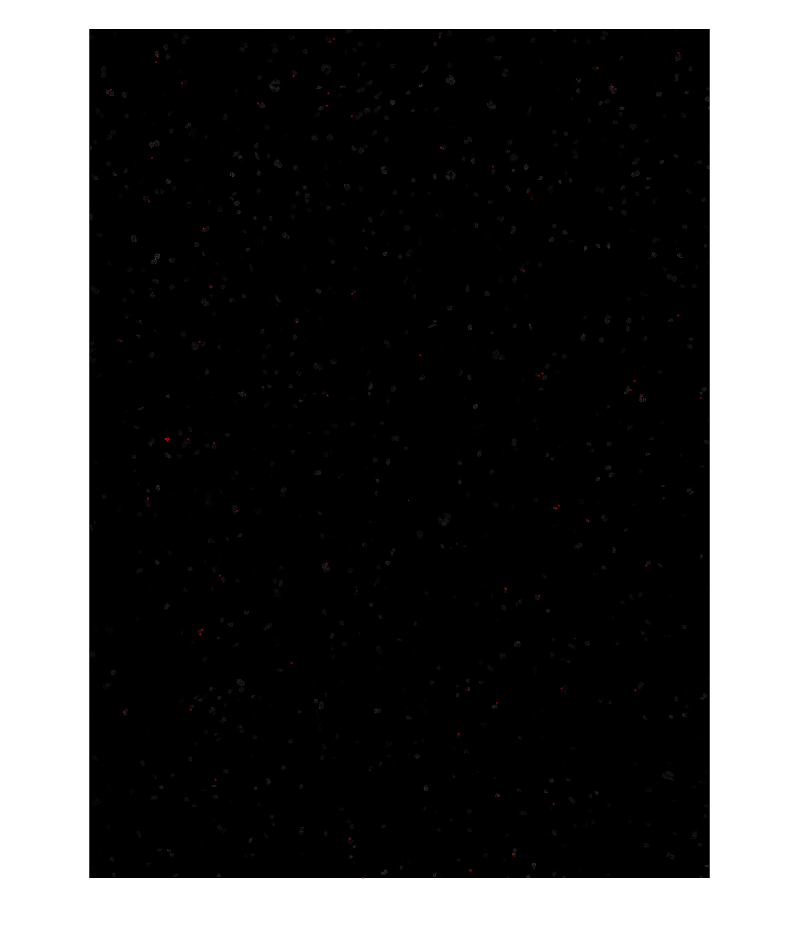


merged_points(:,1) = merged_points(:,1) - 1;
merged_points(:,2) = merged_points(:,2) - 1;
merged_points(:,3) = merged_points(:,3) - 1;

z = 20;
plot_centroids(merged_points(merged_points(:, 3) == z, :), dapi_3d(:,:,z), 1)

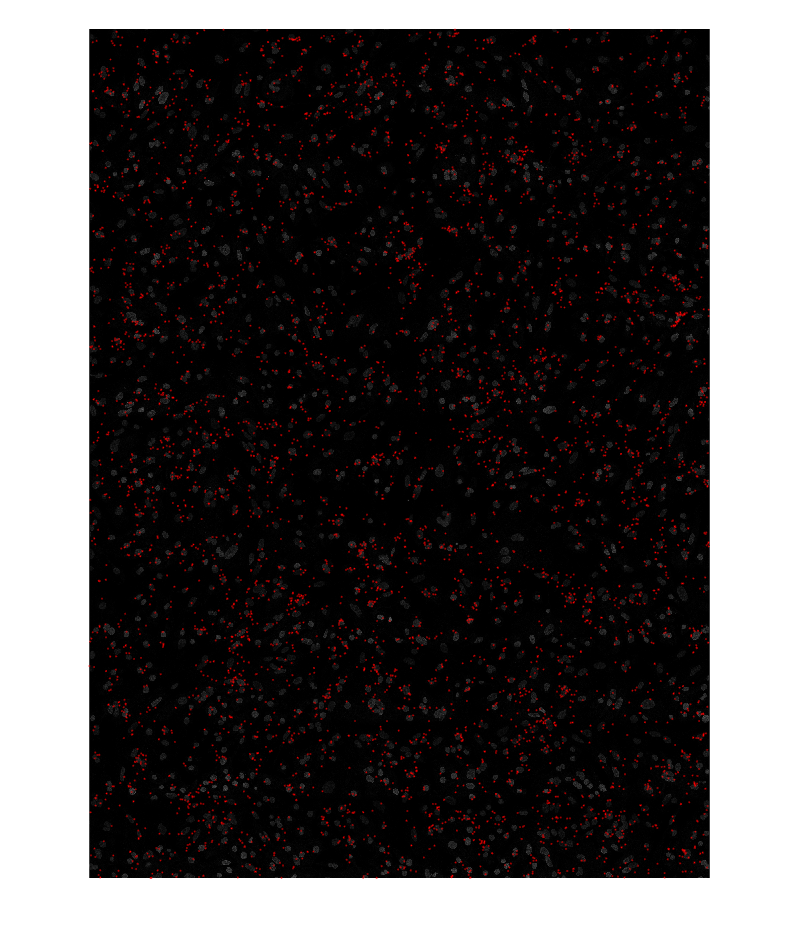


plot_centroids(merged_points, dapi_max, 1)

## output

spot_out_path = fullfile(input_path, '2022-10-15-merged-points', current_well);
if ~exist(spot_out_path, 'dir')
    mkdir(spot_out_path)
end
save(fullfile(input_path, '2022-10-15-merged-points', current_well, 'merged_AF546_points.mat'), "merged_points");